# Получаем mean and std для гауссов

z - звуковой сигнал

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

data - Каждый столбец - звук отдельной **ноты**

NOTES = 88;
data = reshape(z,4*Fs,[]);
NFFT = 1024;

t_one = 2;                  % Одна нота длится 2 секунды
dt = 1/Fs;                  % Время между отчетами
t_min = NFFT*dt;              % Время вырезки
N_row = floor(t_one/t_min); % Количество вырезок за 2 секунды
N = N_row;

mean_pdf = zeros([NFFT/2, NOTES]);
std_pdf = zeros([NFFT/2, NOTES]);

for num_notes = 1 : NOTES
    notes = reshape(data(1:NFFT*N,num_notes),NFFT,N);
    notes = abs(fft(notes));
    mean_pdf(:,num_notes) = mean(notes(1:NFFT/2,:),2);
    std_pdf(:,num_notes) = std(notes(1:NFFT/2,:),1,2);   % Maybe we must set 0 for secod parameter
    
end

Вывожу результаты

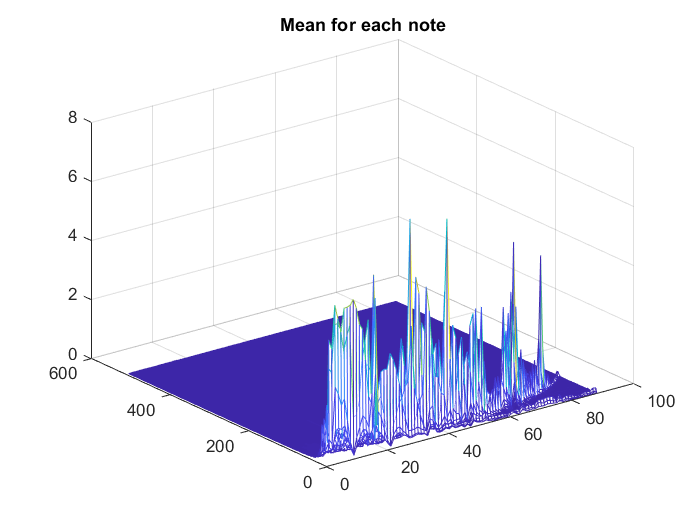

figure 
mesh(mean_pdf)
title('Mean for each note')

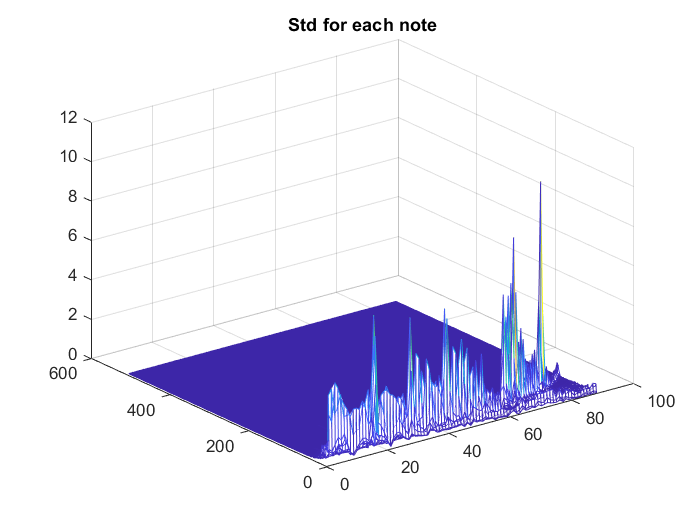


figure 
mesh(std_pdf)
title('Std for each note')

# Обучение по временному сигналу байесовского классификатора

- Each row of X contains features, that represents class filled in corresponding row in Y

- size (X) = N_row*NOTES x NFFT

- size (Y) = N_row*NOTES x 1

Заполняю X and Y

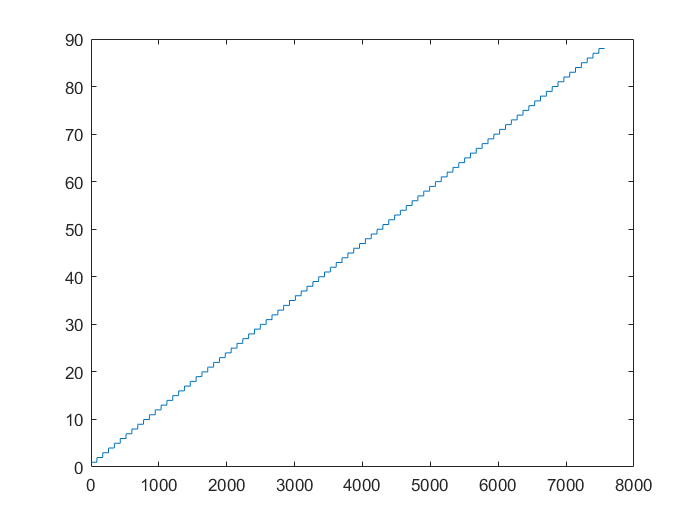

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT]);

N_one = 2 * Fs;             % Кол-во отчетов на 1 ноту
N_shift = 2*N_one;          % Сдвиг по отчетам на ноту

for num_notes = 1 : NOTES
    
    N1 = N * (num_notes-1) + 1;
    N2 = N1 + N - 1;
    
    d = data(1:NFFT*N, num_notes);
    d1 = reshape(d, [N, NFFT]);
    
    X(N1:N2, :) = d1;
    Y(N1:N2) = num_notes;
   
end

figure
plot(Y)

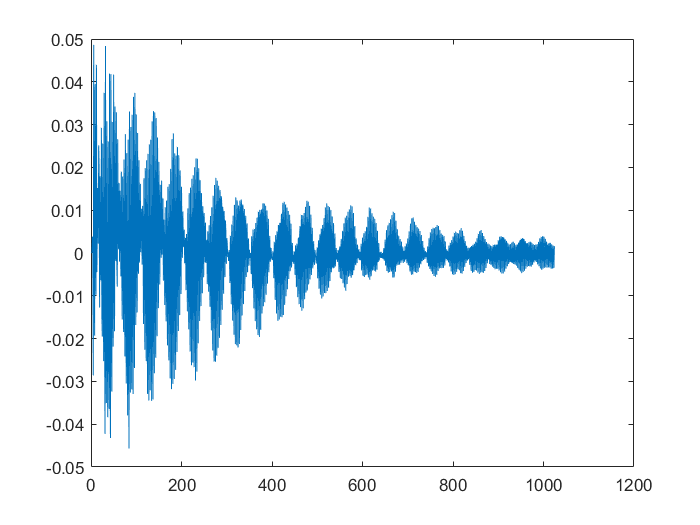


figure
plot(X(2800,:))

Начинаю обучение

Mdl_time = fitcnb(X,Y)

Mdl_time =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1×88 double]
            ScoreTransform: 'none'
           NumObservations: 7568
         DistributionNames: {1×1024 cell}
    DistributionParameters: {88×1024 cell}


  Properties, Methods


Mdl_time.ClassNames

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



CVMdl_time = fitcnb(X,Y,'CrossVal','on')
CVMdl_time.Trained{1}
genError = kfoldLoss(CVMdl_time)

X_spec = abs(fft(X'))';

Mdl_freq = fitcnb(X_spec,Y)
Mdl_freq.ClassNames

CVMdl_freq = fitcnb(X_spec,Y,'CrossVal','on')
CVMdl_freq.Trained{1}
genError = kfoldLoss(CVMdl_freq)

% save('BaiesTrainedFreq.mat', 'CVMdl_freq', 'Mdl_freq')
% save('BaiesTrainedTime.mat', 'CVMdl_time', 'Mdl_time')
save('data.mat', 'data', 'X', 'Y')

# Обучение и Проверка байесовского классификатора

clear all
close all

% load("BaiesTrainedTime.mat");
% load("BaiesTrainedFreq.mat");
load("data.mat");

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

Обучение и Тест

Mdl = fitcnb(XTrain,YTrain);
label = predict(Mdl,XTest);
table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       


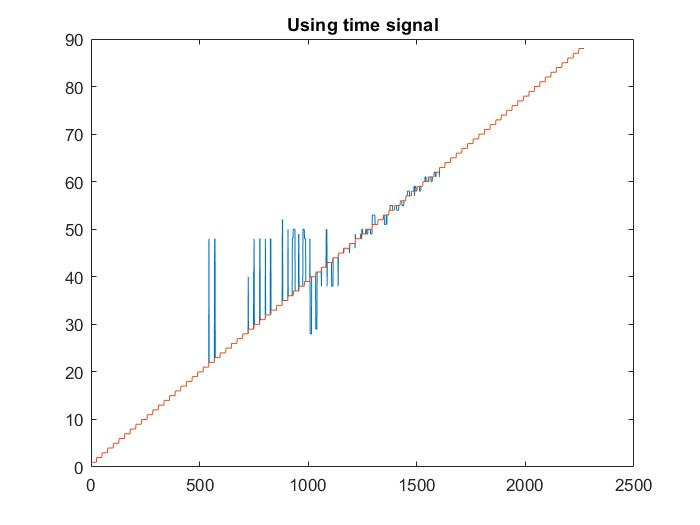


figure
plot(label)
hold on
plot(YTest)
title('Using time signal')

Обучение и Тест по спектрам

for i = 1:length(XTest)
    XTest(i, :) = abs(fft(XTest(i, :)));
end
for i = 1:length(XTrain)
    XTrain(i, :) = abs(fft(XTrain(i, :)));
end

Mdl_freq = fitcnb(XTrain,YTrain);
label = predict(Mdl_freq,XTest);
table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       


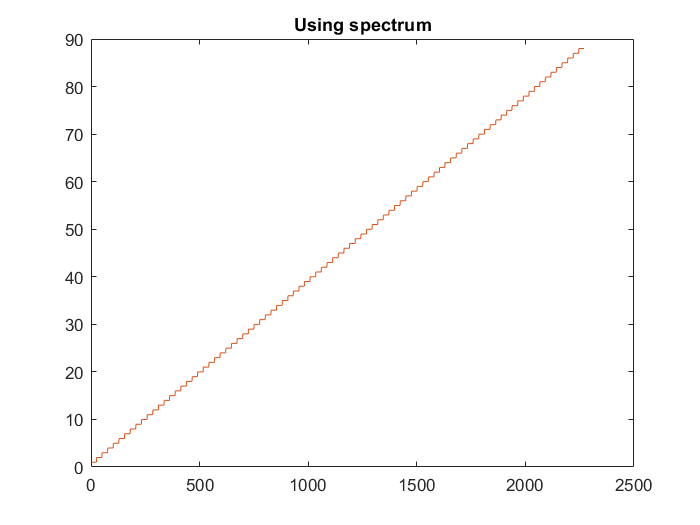


figure
plot(label)
hold on
plot(YTest)
title('Using spectrum')

Пример как брать fft в матрице по строкам (транспонируем и берем по столбцам)

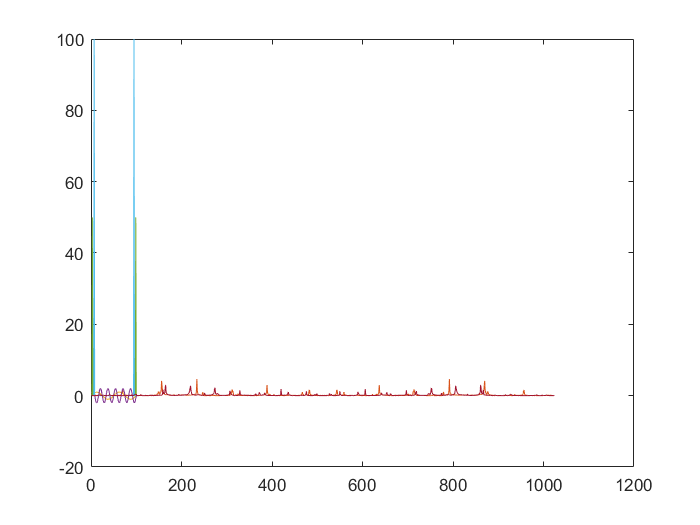

t = 1:100;
w0 = 2*pi/50;
x1 = sin(t*w0);
x2 = 2*sin(3*t*w0);

plot(x1)

plot(x2)

x = [x1; x2];
x_spec = abs(fft(x'));

plot(x_spec(:,1))

plot(x_spec(:,2))

X_spec = abs(fft(X'));

plot(X_spec(:,1))


figure
XX1 = X_spec(:,200)'

XX1 =     0.0026    0.0079    0.0167    0.0097    0.0107    0.0148    0.0218    0.0287    0.0346    0.0498    0.1179    0.1380    0.1717    0.0705    0.0710    0.0418    0.0226    0.0262    0.0382    0.0216    0.0148    0.0242    0.0272    0.0274    0.0402    0.0663    0.1444    0.2174    0.0685    0.0298    0.0193    0.0142    0.0242    0.0232    0.0175    0.0326    0.0647    0.3709    0.0503    0.0478    0.0255    0.0135    0.0157    0.0144    0.0216    0.0127    0.0230    0.0149    0.0192    0.0193


X1 = abs(fft(X(200,:)))

X1 =     0.0026    0.0079    0.0167    0.0097    0.0107    0.0148    0.0218    0.0287    0.0346    0.0498    0.1179    0.1380    0.1717    0.0705    0.0710    0.0418    0.0226    0.0262    0.0382    0.0216    0.0148    0.0242    0.0272    0.0274    0.0402    0.0663    0.1444    0.2174    0.0685    0.0298    0.0193    0.0142    0.0242    0.0232    0.0175    0.0326    0.0647    0.3709    0.0503    0.0478    0.0255    0.0135    0.0157    0.0144    0.0216    0.0127    0.0230    0.0149    0.0192    0.0193


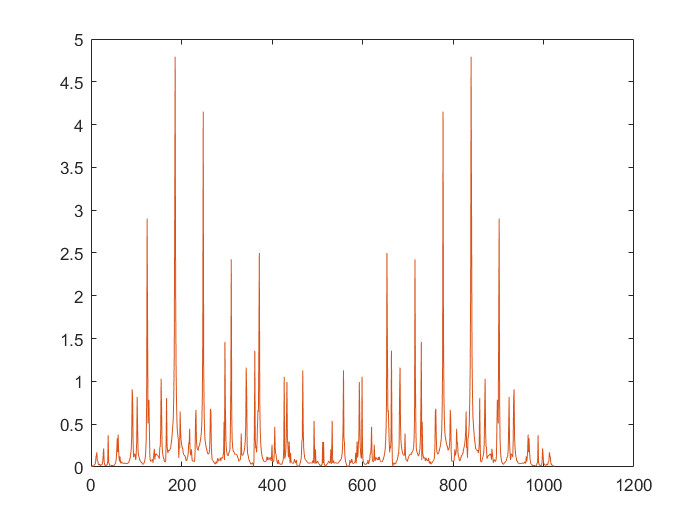

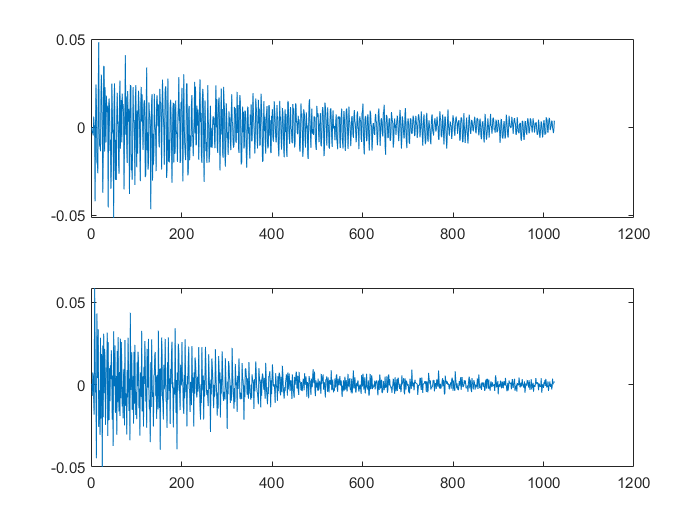

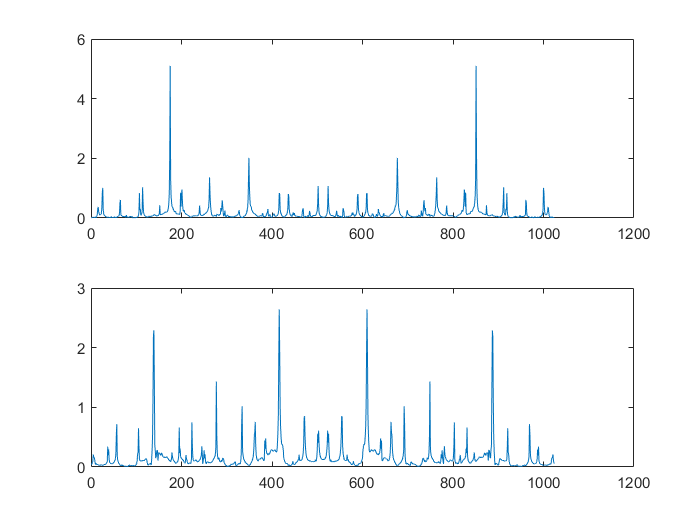

plot(X1)
hold on
plot(XX1)